# Hand Posture Recognition - Hierarchical Clustering

Hierarchical clustering computes pairwise distance matrix. For big arrays, this array becomes too big to fit in the memory, hence we get the error. We feed a subset of the data to our hierarchical clustering algorithm. For each of the five classes, we pick only the first 600 samples after data cleaning & outlier detection. 

## Load data

data_path = 'hand_posture.csv';
%dataset from https://archive.ics.uci.edu/ml/datasets/MoCap+Hand+Postures
hand_pos_data = readtable(data_path, 'TreatAsEmpty',{'?', ' ', '.','NA'});  
%clean the data; Replace the mentioned elements with NaN
%readtable handle all data types present in the table and retains the
%header too, hence it is better than readcsv and readxls

data = hand_pos_data(1:end, 3:20);  
labels = hand_pos_data(1:end, 1);
disp(['Data ', num2str(size(data))])

Data 78095     18


disp(['Dataset consists of ',num2str(size(data,1)), ' samples and ',num2str(size(data,2)),' features '])

Dataset consists of 78095 samples and 18 features 


classes = unique(table2array(labels));
disp(['Classes in dataset: ',num2str(classes')]);

Classes in dataset: 1  2  3  4  5


feature_names = [];  %create a string array containing feature names
for i=1:width(data)
    x = data.Properties.VariableNames(i);
    feature_names = [feature_names, string(x{1})];
end
disp(['Features in data: ', feature_names])

  Columns 1 through 15

    "Features in data: "    "X0"    "Y0"    "Z0"    "X1"    "Y1"    "Z1"    "X2"    "Y2"    "Z2"    "X3"    "Y3"    "Z3"    "X4"    "Y4"

  Columns 16 through 19

    "Z4"    "X5"    "Y5"    "Z5"



## Data cleaning

dataset_array = table2dataset(data); %dataset arrays are arrays for statistical data

messy_data = dataset_array;
%Find samples with missing values
ix = ismissing(messy_data, 'StringTreatAsMissing', {'?',' ','NaN','.','NA'});
[missing_row_idx, ~]  = find(sum(ix,2)~=0);
disp([num2str(length(missing_row_idx)), ' obervations in total have missing values']); 

13023 obervations in total have missing values


disp(['These samples will be removed']);

These samples will be removed


%Create a dataset array with complete observations
%Create the new clean dataset that is = old data minus all missing
%obervations

ix = ismissing(messy_data);  
%logical aray, 1s in locations where data is missing; so we get an array same size as data, with 1 in place of each NaN
clean_data_idx = ~any(ix,2);
cleaned_data = messy_data(clean_data_idx,:); 
y_cleaned = table2array(labels(clean_data_idx, :));

%'any' is a logical array, returns ones in places where any elements are non 0- default is columnwise
%we find indices 
disp(['New cleaned data: ', num2str(size(cleaned_data))]);

New cleaned data: 65072     18


## Find random 600 samples for each class- from 1 to 5

n = 600;
start_idx = 1;
end_idx = n;
n_samples = n*length(classes);  %total samples our new subset of data will contain
X_subset = zeros(n_samples, size(cleaned_data,2)); %we preallocate for speed

for class_num = 1:5
    idx = find(y_cleaned == class_num);  %from original label array, find indices with label = this current one
    rand_idx = randsample(idx, n);  %out of these, pick some at random
    X_subset(start_idx:end_idx, :) = cleaned_data(rand_idx, :);
    start_idx = start_idx + n;
    end_idx = end_idx + n; 
end
disp(['New smaller subset of data: ', num2str(size(X_subset))]);

New smaller subset of data: 3000    18


## Remove outliers

X_norm = mapstd(double(X_subset)')';  %later, we do PCA that needs data normalized along columns
disp(['Normalize data so it has zero mean and unity standard deviation']);

Normalize data so it has zero mean and unity standard deviation


disp(['Data mean = ', num2str(mean(X_norm(:))), ', standard deviation = ', num2str(std(X_norm(:)))]);

Data mean = -1.0129e-16, standard deviation = 0.99984


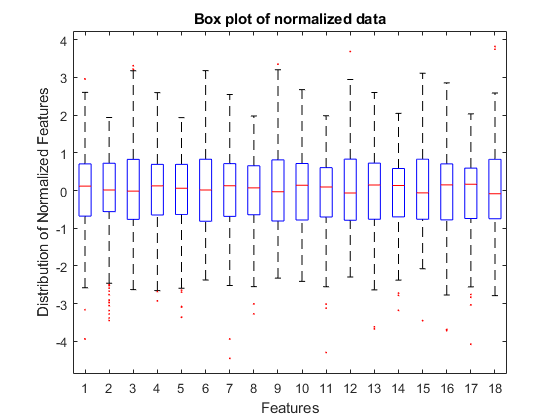

%% View and remove outliers
boxplot(X_norm, 'OutlierSize',1, 'Symbol', 'ro');
title('Box plot of normalized data');
xlabel('Features');
ylabel('Distribution of Normalized Features');

TF = isoutlier(X_norm, 'quartile');
%method is quartile => we eliminate outliers that lie above or below 1.5* IQR(interquartile range = 50 percentitle = Q3-Q1)_
sum_TF = sum(TF,2);  
%sum TF row wise to find samples with outliers; array containing 1 corresponding to samples with outliers
nt_outlier_idx = find(sum_TF == 0);
outlier_idx = find(sum_TF ~= 0);
disp(['Data consists of ', num2str(length(outlier_idx)), ' outliers.']);

Data consists of 34 outliers.


X_outliers_rmvd = X_norm(nt_outlier_idx, :);
disp(['Data after outlier removal: ', num2str(size(X_outliers_rmvd))]);

Data after outlier removal: 2966    18


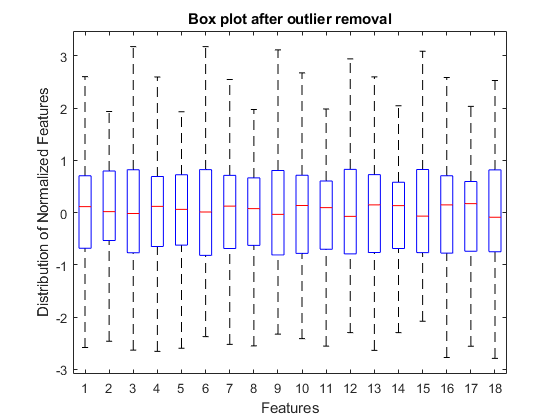

boxplot(X_outliers_rmvd);
title('Box plot after outlier removal');
xlabel('Features');
ylabel('Distribution of Normalized Features');

## Elbow plot to find optimum number of principal components

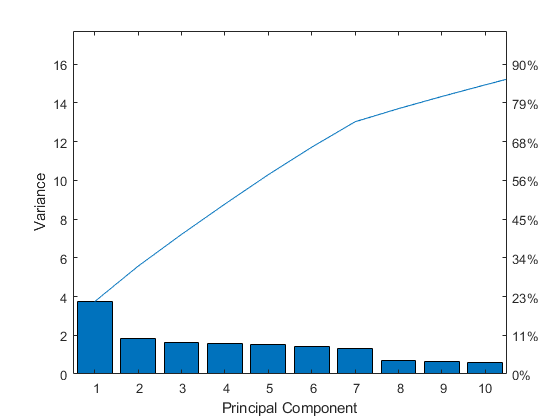

[loadings, X_pca_, variances, tscores] = pca(X_outliers_rmvd);
figure;
pareto(variances);
xlabel('Principal Component')
ylabel('Variance')

n_comp = 2; %we consider only the first 2 components, since we do not see a clear 'elbow'
X_pca = X_pca_(:, 1:n_comp);
disp(['Data after PCA: ', num2str(size(X_pca))]);

Data after PCA: 2966     2


## Run parallel pool

p = gcp('nocreate');
if isempty(p)
    p = parpool('local');
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.


## Hierarchical Clustering- average linkage

% Create cluster of trees
distance_measure = pdist(X_pca, 'cosine');      %distance between pairs of observations in X
% create hierarchical cluster tree
cluster_tree = linkage(distance_measure, 'average');  %average= average distance
% Compute cophenetic correlation
% - verify that the cluster tree is consistent with the original distances
coph_corr = cophenet(cluster_tree, distance_measure)

coph_corr = 0.7440

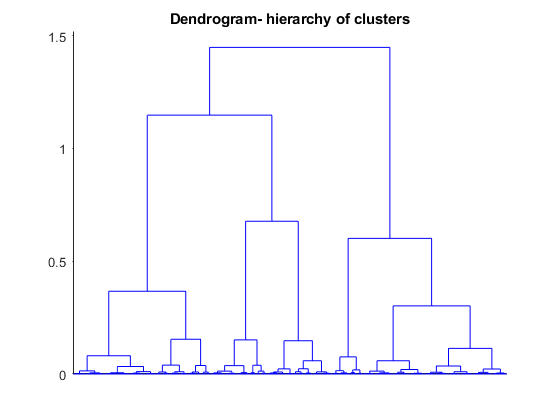

% a high value implies that the tree is a fairly good fit to the distances

%  Dendrogram - visualize the hierarchy of clusters
[h,nodes] = dendrogram(cluster_tree, 0);   %0: no limit on the number of leaf nodes
h_gca = gca;
h_gca.TickDir = 'out';
title('Dendrogram- hierarchy of clusters')
h_gca.TickLength = [.002 0];
h_gca.XTickLabel = [];

## Visualize clustered data

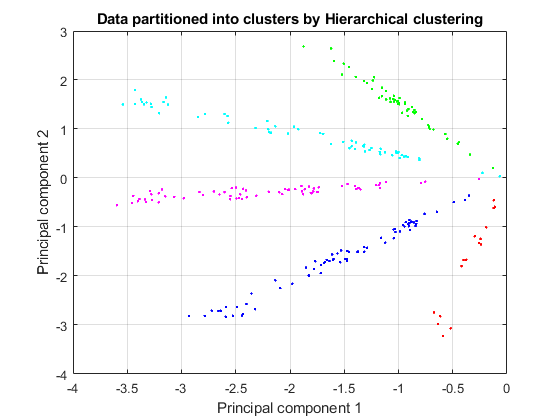

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
for i = 1:5
    clust = find(idx==i);
    plot(X_pca(clust,1), X_pca(clust,2),ptsymb{i});
    hold on
end
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
title('Data partitioned into clusters by Hierarchical clustering')
grid on

disp(['Hierarchical cluster tree organized data into ', num2str(length(unique(idx))), ' clusters'])

Hierarchical cluster tree organized data into 45 clusters


## Reduce the number of leaf nodes

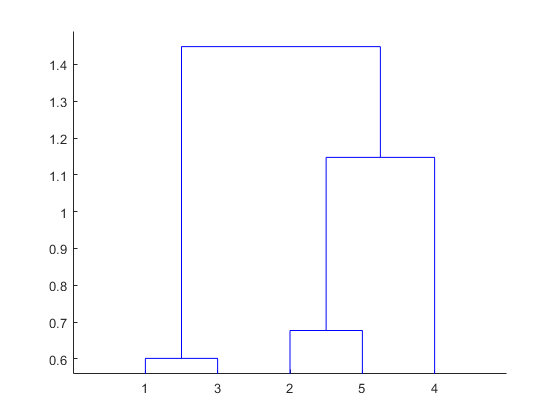

% - if we don't want to display the very lowest levels of the tree
[h,nodes] = dendrogram(cluster_tree, 5); %tree will show these many leaf nodes

% Compute the number of samples belonging to each cluster
n_samples = [sum(ismember(nodes,[1 3])) sum(nodes == 2)...
    sum(nodes == 5) sum(nodes==4)];
disp(['Number of samples in each of the highest nodes : ', num2str(n_samples)])

Number of samples in each of the highest nodes : 1198   391   442   935


## Hierarchical Clustering- with cosine distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'cosine');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.6740]



Data was partioned into 81 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.7824]



Data was partioned into 1 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.7471]



Data was partioned into 101 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.7740]



Data was partioned into 48 clusters


## Hierarchical Clustering- with euclidean distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'euclidean');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.5382]



Data was partioned into 2950 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.4284]



Data was partioned into 2950 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5934]



Data was partioned into 2950 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.5912]



Data was partioned into 2950 clusters


## Hierarchical Clustering- with `squaredeuclidean` distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'squaredeuclidean');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.4490]



Data was partioned into 1791 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.3370]



Data was partioned into 1273 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5378]



Data was partioned into 1775 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.4405]



Data was partioned into 1706 clusters


## Hierarchical Clustering- with mahalanobis distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'mahalanobis');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.5642]



Data was partioned into 2919 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.4588]



Data was partioned into 2918 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5481]



Data was partioned into 2919 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.5323]



Data was partioned into 2918 clusters


## Hierarchical Clustering- with cityblock distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'cityblock');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.5278]



Data was partioned into 2957 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.4322]



Data was partioned into 2957 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5168]



Data was partioned into 2957 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.5798]



Data was partioned into 2957 clusters


## Hierarchical Clustering- with minkowski distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'minkowski');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.5382]



Data was partioned into 2950 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.4284]



Data was partioned into 2950 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5934]



Data was partioned into 2950 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.5912]



Data was partioned into 2950 clusters


## Hierarchical Clustering- with chebychev distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'chebychev');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [0.5920]



Data was partioned into 2947 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [0.3923]



Data was partioned into 2946 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [0.5893]



Data was partioned into 2947 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [0.5260]



Data was partioned into 2947 clusters


## Hierarchical Clustering- with correlation distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'correlation');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [1.0000]



Data was partioned into 2 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [1.0000]



Data was partioned into 2 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [1.0000]



Data was partioned into 2 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [1.0000]



Data was partioned into 2 clusters


## Hierarchical Clustering- with hamming distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'hamming');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


## Hierarchical Clustering- with jaccard distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'jaccard');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', coph_corr])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    [NaN]



Data was partioned into 2966 clusters


## Hierarchical Clustering- with spearman distance metric, try different linkages

% Create cluster of trees
distance_measure = pdist(X_pca, 'spearman');      %distance between pairs of observations in X

for linkage_method = {'complete', 'single', 'ward', 'weighted'}
    cluster_tree = linkage(distance_measure, linkage_method);  %average= average distance
    % Compute cophenetic correlation
    % - verify that the cluster tree is consistent with the original distances
    coph_corr = cophenet(cluster_tree, distance_measure);
    idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
    disp(['For linkage = ', linkage_method, ' cophenetic correlation = ', num2str(coph_corr)])
    disp(['Data was partioned into ', num2str(length(unique(idx))), ' clusters'])
end

    'For linkage = '    'complete'    ' cophenetic correlation = '    '1'



Data was partioned into 2 clusters


    'For linkage = '    'single'    ' cophenetic correlation = '    '1'



Data was partioned into 2 clusters


    'For linkage = '    'ward'    ' cophenetic correlation = '    '1'



Data was partioned into 2 clusters


    'For linkage = '    'weighted'    ' cophenetic correlation = '    '1'



Data was partioned into 2 clusters


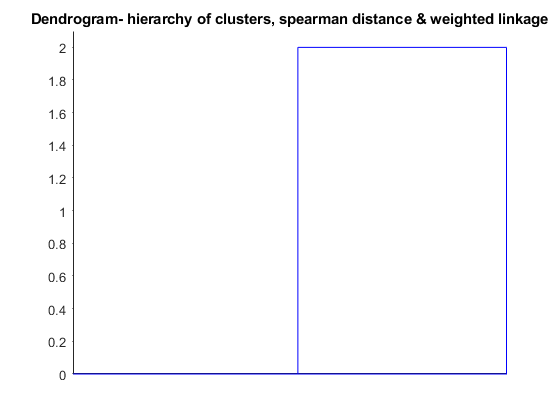

[h,nodes] = dendrogram(cluster_tree, 0);   %0: no limit on the number of leaf nodes
h_gca = gca;
h_gca.TickDir = 'out';
title('Dendrogram- hierarchy of clusters, spearman distance & weighted linkage')
h_gca.TickLength = [.002 0];
h_gca.XTickLabel = [];

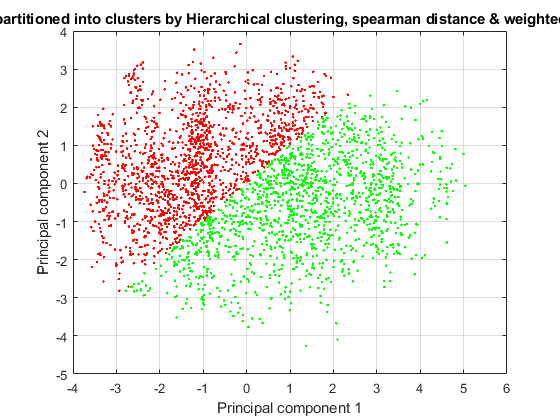

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
idx = cluster(cluster_tree,'criterion','distance','cutoff',.006); %contruct clusters from cluster tree
for i = 1:5
    clust = find(idx==i);
    plot(X_pca(clust,1), X_pca(clust,2),ptsymb{i});
    hold on
end
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
title('Data partitioned into clusters by Hierarchical clustering, spearman distance & weighted linkage')
grid on